clear
% #1610
% Find the arc length of the curve
% y^2=x^3 frhom x=0 to x=1

syms x y;
f=y^2-x^3

$$f = y^{2}-x^{3}$$

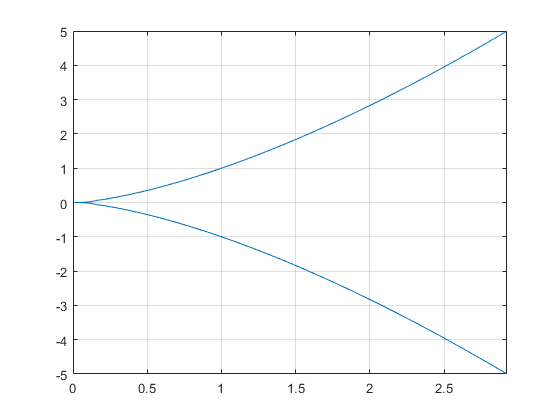

fimplicit(f)
grid

% L = int (a-b) sqrt(1+diff(y)^2) dx
L=int(sqrt(1+diff(x^(3/2))^2),0,1)

$$L = \frac{13\,\sqrt{13}}{27}-\frac{8}{27}$$

% (13*13^(1/2))/27 - 8/27

% #1611
% Find the arc length of the curve
% x=cos(t)^5,y=sin(t)^5 frhom x1=0 to t2=pi/2

% L = int (t1-t2) sqrt(diff(x)^2+diff(y)^2) dt
clear
syms t real;
x=cos(t)^5, y=sin(t)^5

$$x = {\cos\left(t\right)}^{5}$$

$$y = {\sin\left(t\right)}^{5}$$

c=simplify(sqrt(diff(x,t)^2+diff(y,t)^2))

$$c = \frac{5\,\sqrt{2}\,\left|\cos\left(t\right)\right|\,\left|\sin\left(t\right)\right|\,\sqrt{3\,\cos\left(4\,t\right)+5}}{4}$$

L=simplify(int(c,0,pi/2))

$$L = \frac{5}{4}-\frac{5\,\sqrt{3}\,\log\left(7-4\,\sqrt{3}\right)}{48}$$

% Correct answer
% L=5/8*(2-log(2-sqrt(3))/sqrt(3))

% #1612
% Find the arc length of the curve
% rho=sin(theta/3)^3, frhom theta1=0 to theta2=pi/2

% L = int (alfa-beta) sqrt(rho^2+diff(rho)^2) d_theta
syms theta real;
rho=sin(theta/3)^3

$$rho = {\sin\left(\frac{\theta }{3}\right)}^{3}$$

drho=diff(rho)

$$drho = \cos\left(\frac{\theta }{3}\right)\,{\sin\left(\frac{\theta }{3}\right)}^{2}$$

% pi/4 - (3*3^(1/2))/8

c=simplify(sqrt(rho^2+drho^2))

$$c = {\sin\left(\frac{\theta }{3}\right)}^{2}$$

L=int(c,theta,0,pi/2)

$$L = \frac{\pi }{4}-\frac{3\,\sqrt{3}}{8}$$

% pi/4 - (3*3^(1/2))/8

% #1613
% Calculate the arc length of a curve
% y=log(sin(x)), pi/3<=x<=pi/2

% L =  int (a-b) sqrt(1+diff(y)^2) dx
syms x real;
y=log(sin(x))

$$y = \log\left(\sin\left(x\right)\right)$$

c=simplify(sqrt(1+diff(y)^2))

$$c = \frac{1}{\left|\sin\left(x\right)\right|}$$

L=int(c,x,pi/3,pi/2)

$$L = \frac{\log\left(3\right)}{2}$$

% log(3)/2

% #1614
% Calculate the arc length of a curve
% y=2/5*x*x^(1/4)-2/3*x^(3/4)
% between points of intersection with the axis Ox

% L = int (a-b) sqrt(1+diff(y)^2) dx
syms x real;
y=2/5*x*x^(1/4)-2/3*x^(3/4)

$$y = \frac{2\,x^{5/4}}{5}-\frac{2\,x^{3/4}}{3}$$

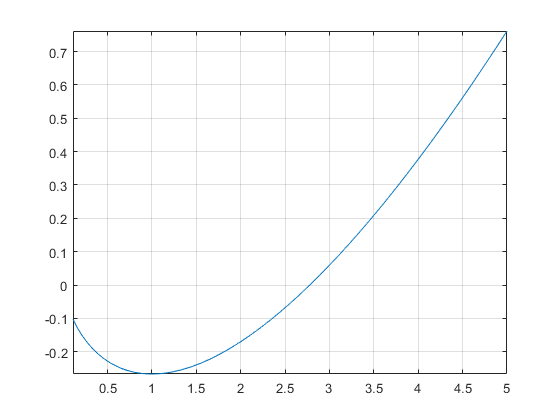

fplot(y)
grid


slv=solve(y==0)

$$slv = \left(\begin{array}{c} 0\\ \frac{25}{9} \end{array}\right)$$

c=simplify(sqrt(1+diff(y)^2))

$$c = \frac{\sqrt{\frac{{\left(\sqrt{x}+1\right)}^{2}}{\sqrt{x}}}}{2}$$

L=int(c,x,0,25/9)

$$L = \frac{20\,\sqrt{15}}{27}$$

% (20*15^(1/2))/27

% #1615
% Calculate the arc length of a curve
% y=x^2/2, 0<=x<=1

% L = int (a-b) sqrt(1+diff(y)^2) dx
syms x real;
y=x^2/2

$$y = \frac{x^{2}}{2}$$

c=sqrt(1+diff(y)^2)

$$c = \sqrt{x^{2}+1}$$

L=int(c,x,0,1)

$$L = \frac{\log\left(\sqrt{2}+1\right)}{2}+\frac{\sqrt{2}}{2}$$

% log(2^(1/2) + 1)/2 + 2^(1/2)/2